# Padé approximation of cosine

This file contains the code to approximate cosine using Padé approximation. The `pade` function provides approximation for many functions.

**Preparation**: Clear everything and set formatting.

clc
format loose
format short

syms x
f = cos(x) % f is the cosine value of x

$$f = \cos\left(x\right)$$

**Approximation**: Try to find the best approximant of cosine.

*Note*:

- Drag the slider to adjust the center of the Padé approximant.

- 0 seems to produce a clear and simple output.

a =0

a = 0


% 1 is the best for now...
% error: 0.0105

g = pade(f, x, a, 'Order', [6 5])

$$g = -\frac{59\,x^{6}-3814\,x^{4}+62160\,x^{2}-131040}{2\,\left(17\,x^{4}+1680\,x^{2}+65520\right)}$$

e = abs(f - g)

$$e = \left|\cos\left(x\right)+\frac{59\,x^{6}-3814\,x^{4}+62160\,x^{2}-131040}{2\,\left(17\,x^{4}+1680\,x^{2}+65520\right)}\right|$$

**Evaluation**: Find the errors of the approximation.

x_values = linspace(0, 1, 1e2)

x_values =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


err = double(subs(e, x, x_values))

err = 1.0e-08 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


mean(err, 'omitnan')

ans = 1.1372e-10

**Visualization**: Graph the errors and see the covergence.

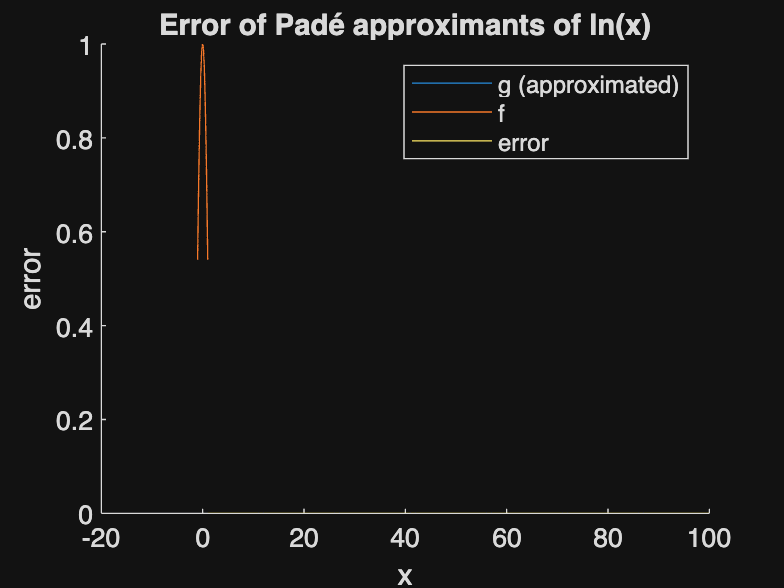

figure
hold off
hold on
fplot(g, [-1 1])
fplot(f, [-1 1])
plot(err)

title('Error of Padé approximants of ln(x)')
legend('g (approximated)', 'f', 'error')
xlabel('x')
ylabel('error')